# Exercise 1 (plot the joint space trajectory)

Compute and plot the joint space trajectory for a Puma 560 manipulator corresponding to a straight segment and a circle in the work space. Discuss and comment the situations in which the inverse kinematics service does not converge using the manipulability measures.

clear all
close all
clc

addpath .\Functions;
mdl_puma560;
p560_nofric = p560.nofriction;  % to create the non-friction model of the Puma560


## Linear trajectory

**Parameters**

start_point = [0.6, -0.5, 0.0];
dest_point = [0.4, 0.5, 0.2];

Changing the destination point with a bigger value we can end up in a situation where the robot cannot physically reach that position

%dest_point = [1.4, 1.5, 1.2];

n_step = 100;

step_size = 0.01;

sing_cfg = 0;    % not singular
sing_cfg_1 = 1;  % q5=0, true singular configuration q4=q5=q6=0

**Trajectories making (Singular configuration pi/4)**

qq_linear = Function_trajLine(start_point, dest_point, p560, n_step, sing_cfg);

**Manipulability check (Singular configuration pi/4)**

m_linear = p560.maniplty(qq_linear);    %manipulability measure

**Plot (Singular configuration pi/4)**

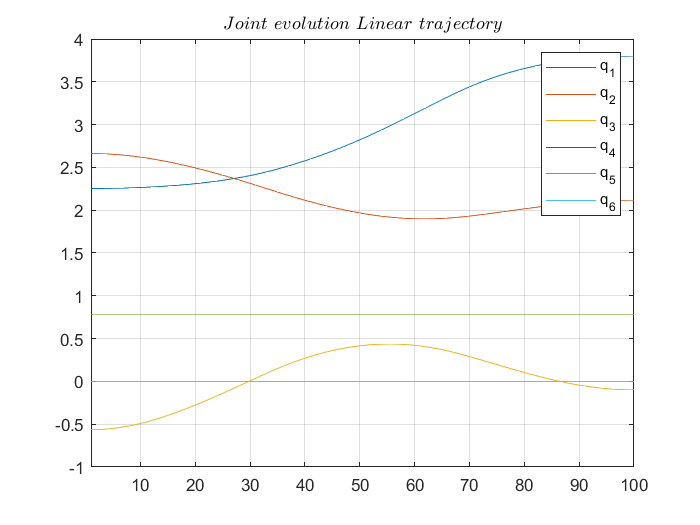

figure(1)
plot(p560,qq_linear);
title('puma560 Linear Trajectory');


figure(2)
plot([1:n_step], qq_linear);
title('$$Joint\ evolution\ Linear\ trajectory$$', 'Interpreter', 'LaTeX');
axis([1 n_step -1 4]);
legend('q_1', 'q_2', 'q_3', 'q_4', 'q_5', 'q_6');
grid on

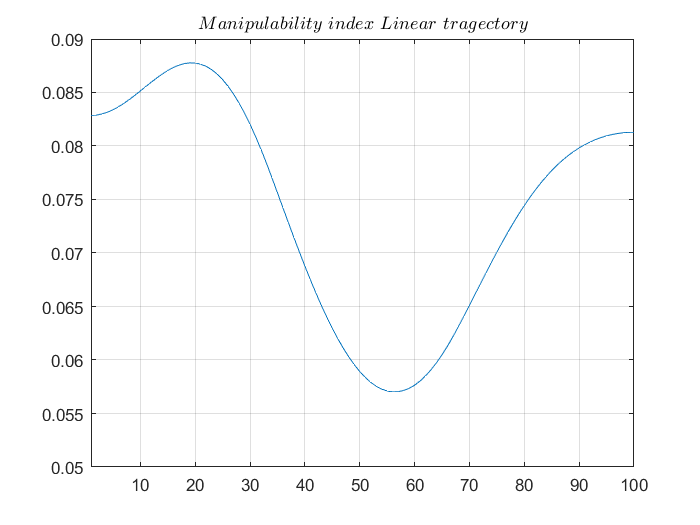


figure(3)
plot([1:n_step], m_linear);
title('$$Manipulability\ index\ Linear\ tragectory $$', 'Interpreter', 'LaTeX');
axis([1 n_step 0 0.1]);
ylim([0.05,0.09])
grid on

**Trajectories making (Singular configuration 0)**

qq_linear_1 = Function_trajLine(start_point, dest_point, p560, n_step, sing_cfg_1);

**Manipulability check (Singular configuration 0)**

m_linear_1 = p560.maniplty(qq_linear_1);    %manipulability measure

**Plot (Singular configuration 0)**

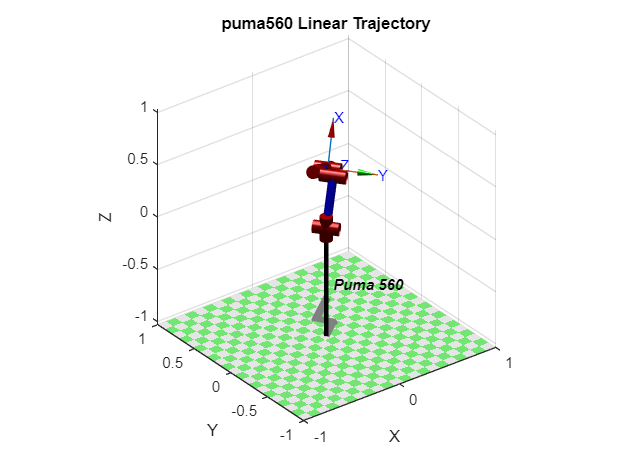

% figure(10)
% plot(p560,qq_linear_1);

% title('puma560 Linear Trajectory');

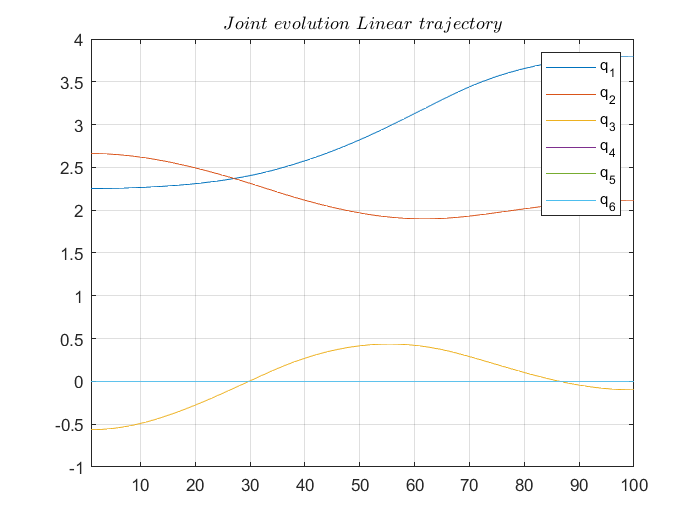

figure(11)
plot([1:n_step], qq_linear_1);
title('$$Joint\ evolution\ Linear\ trajectory$$', 'Interpreter', 'LaTeX');
axis([1 n_step -1 4]);
legend('q_1', 'q_2', 'q_3', 'q_4', 'q_5', 'q_6');
grid on

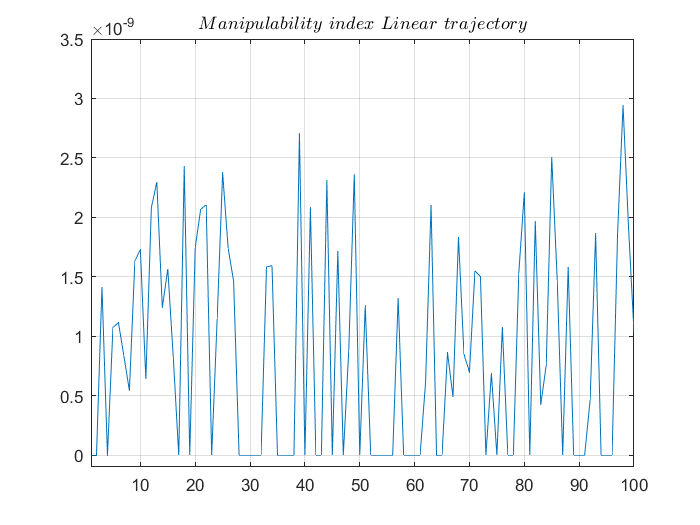

figure(12)
plot([1:n_step], m_linear_1);
title('$$Manipulability\ index\ Linear\ trajectory$$', 'Interpreter', 'LaTeX');
axis([1 n_step -0.1e-9 3.5e-9]);
grid on

## Circular trajectory

**Parameters**

rad_circle = 0.3;
x_center = 0.4;
y_center = -0.3;

**Trajectories making (Singular configuration q5=pi/4)**

qq_circular = Function_trajCircle(rad_circle, x_center, y_center, p560, n_step, sing_cfg);
m_circular = p560.maniplty(qq_circular);    %manipulability measure

**Plot (Singular configuration q5=pi/4)**

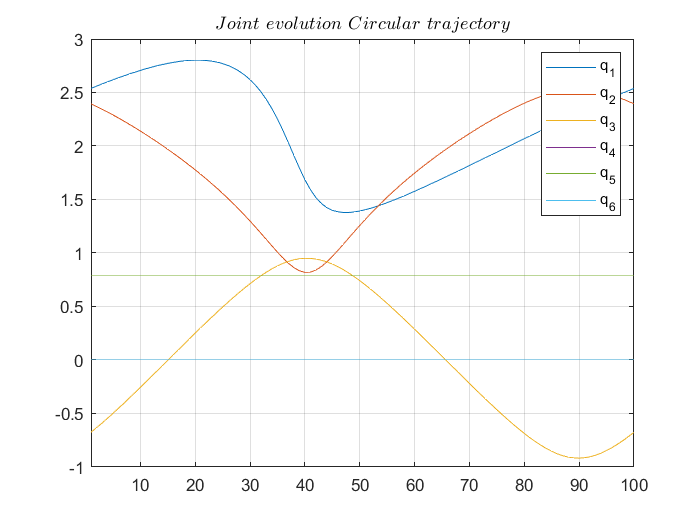

% figure(20)
% plot(p560,qq_circular);
% title('puma560 Circular Trajectory');

figure(21)
plot([1:n_step], qq_circular);
title('$$Joint\ evolution\ Circular\ trajectory$$', 'Interpreter', 'LaTeX');
axis([1 n_step -1 3]);
legend('q_1', 'q_2', 'q_3', 'q_4', 'q_5', 'q_6');
grid on

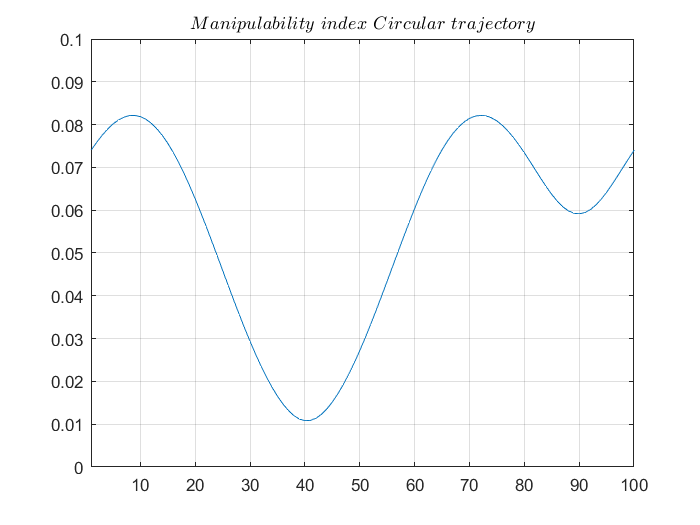



figure(22)
plot([1:n_step], m_circular);
title('$$Manipulability\ index\ Circular\ trajectory$$', 'Interpreter', 'LaTeX');
axis([1 n_step 0 0.1]);
grid on

**Trajectories making (Singular configuration q5=0)**

qq_circular_1 = Function_trajCircle(rad_circle, x_center, y_center, p560, n_step, sing_cfg_1);
m_circular_1 = p560.maniplty(qq_circular_1);    %manipulability measure

**Plot (Singular configuration q5=0)**

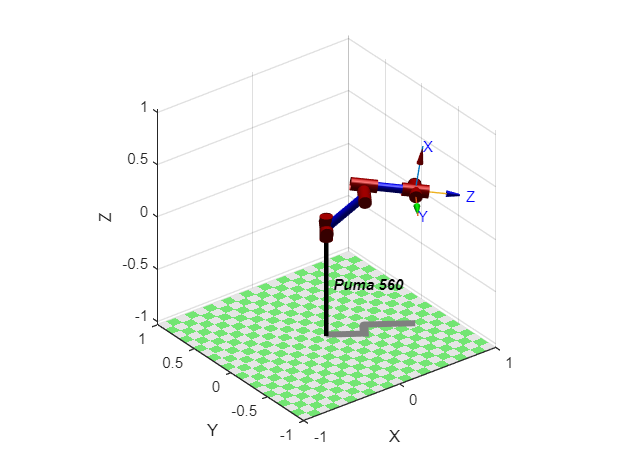

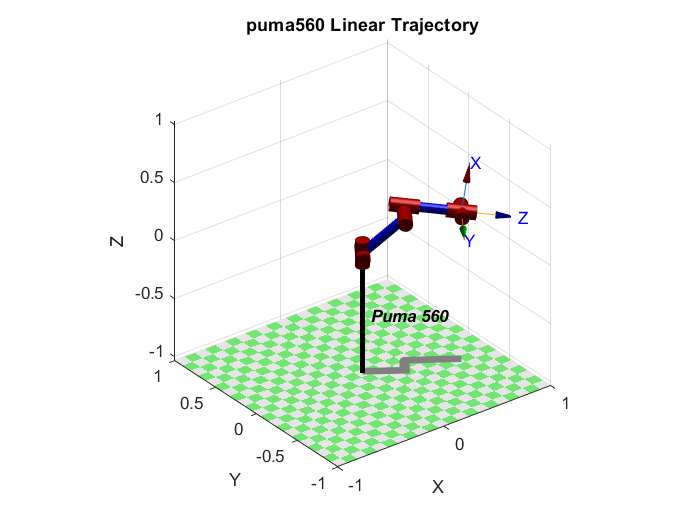

figure(30)
plot(p560,qq_circular_1);

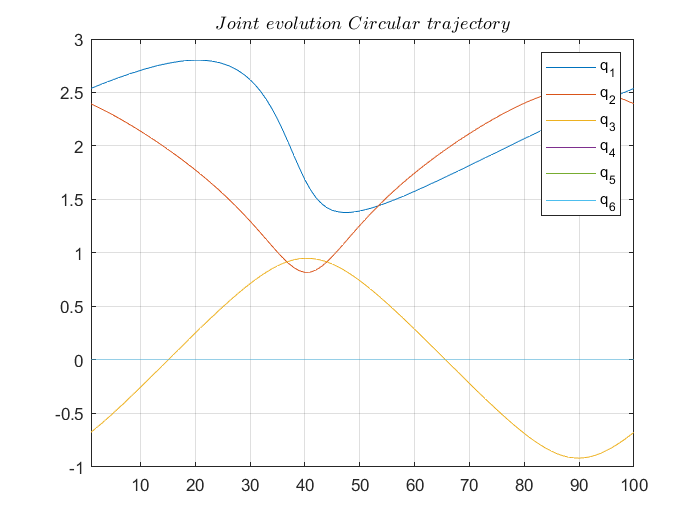


figure(31)
plot([1:n_step], qq_circular_1);
title('$$Joint\ evolution\ Circular\ trajectory$$', 'Interpreter', 'LaTeX');
axis([1 n_step -1 3]);
legend('q_1', 'q_2', 'q_3', 'q_4', 'q_5', 'q_6');
grid on

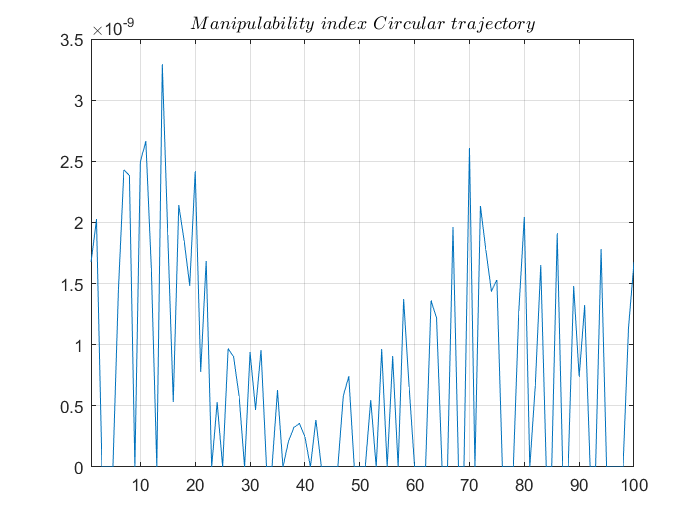





figure(32)
plot([1:n_step], m_circular_1);
title('$$Manipulability\ index\ Circular\ trajectory$$', 'Interpreter', 'LaTeX');
axis([1 n_step 0 3.5e-9]);
grid on

# Exercise 2 (PD+gravity compensation)

Implement a PD+gravity compensation controller for a Puma 560 manipulator and control the robot along the previously computed trajectory. Discuss the stability and tracking properties of the scheme in relation to different choices of the gains.

**Parameters**

% w_n = [1;1;1;1;1;1];
w_n = [10;10;10;10;10;10];
% w_n = [20;20;20;20;20;20]; % since on the matrix Kp we need w_n^2  
w_n_squared = w_n.*w_n;
Kp = diag(w_n_squared)

Kp =    100     0     0     0     0     0
     0   100     0     0     0     0
     0     0   100     0     0     0
     0     0     0   100     0     0
     0     0     0     0   100     0
     0     0     0     0     0   100



% delta = [1;1;1;1;1;1];
delta = [2;2;2;2;2;2];
delta_wni= 2*w_n.*delta;
Kd = diag(delta_wni)

Kd =     40     0     0     0     0     0
     0    40     0     0     0     0
     0     0    40     0     0     0
     0     0     0    40     0     0
     0     0     0     0    40     0
     0     0     0     0     0    40


**Signal for Simulink**

tfin = 2;
timegran = size(qq_circular);
timestep = timegran(1);
t = linspace(0, tfin, timestep);
qqr = qq_circular;      % you can change it with qq_circular_1
qql = qq_linear;        % you can change it with qq_linear_1
qqsr = [t' qq_circular];
qqsr(:,6) = pi/4; % to avoid singular configuration

qqsl = [t' qq_linear];
qqsl(:,6) = pi/4; % to avoid singular configuration

probabilmente non serve puoi togliere le due righe sotto tanto c'è simulink

% figure(100)
% plot(qql_slx); 
% grid on; 
% legend('$$q_1$$', '$$q_2$$', '$$q_3$$', '$$q_4$$', '$$q_5$$', '$$q_6$$', 'Interpreter', 'LaTeX');
% title('$$q(t)$$', 'Interpreter', 'LaTeX');
% xlabel('$$t$$', 'Interprete', 'LaTeX');
% 
% figure(101)
% plot(eql); 
% grid on; 
% legend('$$\tilde{q_1}$$', '$$\tilde{q_2}$$', '$$\tilde{q_3}$$', '$$\tilde{q_4}$$', '$$\tilde{q_5}$$', '$$\tilde{q_6}$$', 'Interpreter', 'LaTeX');
% title('$$\tilde{q}(t)$$', 'Interpreter', 'LaTeX');
% xlim([0 5])
% xlabel('$$t$$', 'Interpreter', 'LaTeX');
% 
% figure(110)
% plot(qqr_slx); 
% grid on; 
% legend('$$q_1$$', '$$q_2$$', '$$q_3$$', '$$q_4$$', '$$q_5$$', '$$q_6$$', 'Interpreter', 'LaTeX');
% title('$$q(t)$$', 'Interpreter', 'LaTeX');
% xlabel('$$t$$', 'Interpreter', 'LaTeX');
% 
% figure(111)
% plot(eqr); 
% grid on; 
% legend('$$\tilde{q_1}$$', '$$\tilde{q_2}$$', '$$\tilde{q_3}$$', '$$\tilde{q_4}$$', '$$\tilde{q_5}$$', '$$\tilde{q_6}$$', 'Interpreter', 'LaTeX');
% title('$$\tilde{q}(t)$$', 'Interpreter', 'LaTeX');
% xlabel('$$t$$', 'Interpreter', 'LaTeX');
